# SimpleHarmonicOscillatorAndResonancePASCOFit

Read and fit data from PASCO system to a damped oscillation form. The data has the form

Run #1	Run #1	Run #1	Run #1	Run #1

	Date and Time	Time (s)	Position (m)	Velocity (m/s)	Acceleration (m/sÂ²)

	11/11/2019 02:52:45 pm	0.000	0.890		

	11/11/2019 02:52:45 pm	0.050	0.898	0.02	

	11/11/2019 02:52:45 pm	0.100	0.892	-0.21	-4.4

	11/11/2019 02:52:45 pm	0.150	0.878	-0.42	-3.9

where the velocities are computed by the PASCO software from the position differences and the accelerations from the velocity differences. We fit the positions to an analyticl form from which the velocities and accelerations might be derived by differentiation.

Author: D. Carlsmith

clear;

Import data using a function (attached) autogenerated by the Import tool.

FILENAME='PASCOOscillationDat.txt';
[VARNAME1, DATEANDTIME, Times, Positionm, VELOCITYMS, ACCELERATIONMS]= ...
    importfile(FILENAME);
halftime=max(Times)/2;
range=Times>0;

Define the model function.

mdlfunction=@(b,t)(b(1)+b(2).*exp(-t*b(3)).*cos(  2*pi*b(4)*t+b(5) ) );...
    %+b(6).*cos( ((2*pi)/b(7))*t+b(8))

Set initial values for the parameters.

b0=[0.7 .15 1/30 26/32 -pi/2];% .05 1 0];

 Fit the data using f`itnlm`, catching a structure `S` with fit information

S=fitnlm(Times(range),Positionm(range),mdlfunction,b0)

S = Nonlinear regression model:
    y ~ (b1 + b2*exp( - t*b3)*cos(2*pi*b4*t + b5))

Estimated Coefficients:
          Estimate        SE         tStat     pValue
          ________    __________    _______    ______

    b1     0.71993    0.00010742     6702.1      0   
    b2    -0.17177    0.00042898    -400.43      0   
    b3    0.052874    0.00023014     229.74      0   
    b4     0.85508    3.6739e-05      23274      0   
    b5     -3.4831     0.0025212    -1381.5      0   


Number of observations: 619, Error degrees of freedom: 614
Root Mean Squared Error: 0.00267
R-Squared: 0.998,  Adjusted R-Squared 0.998
F-statistic vs. constant model: 9.41e+04, p-value = 0

Parameter values and their standard errors.

b0=S.Coefficients.Estimate;
b0err=S.Coefficients.SE;

Plot the data with fit superposed nad plot the residuals.

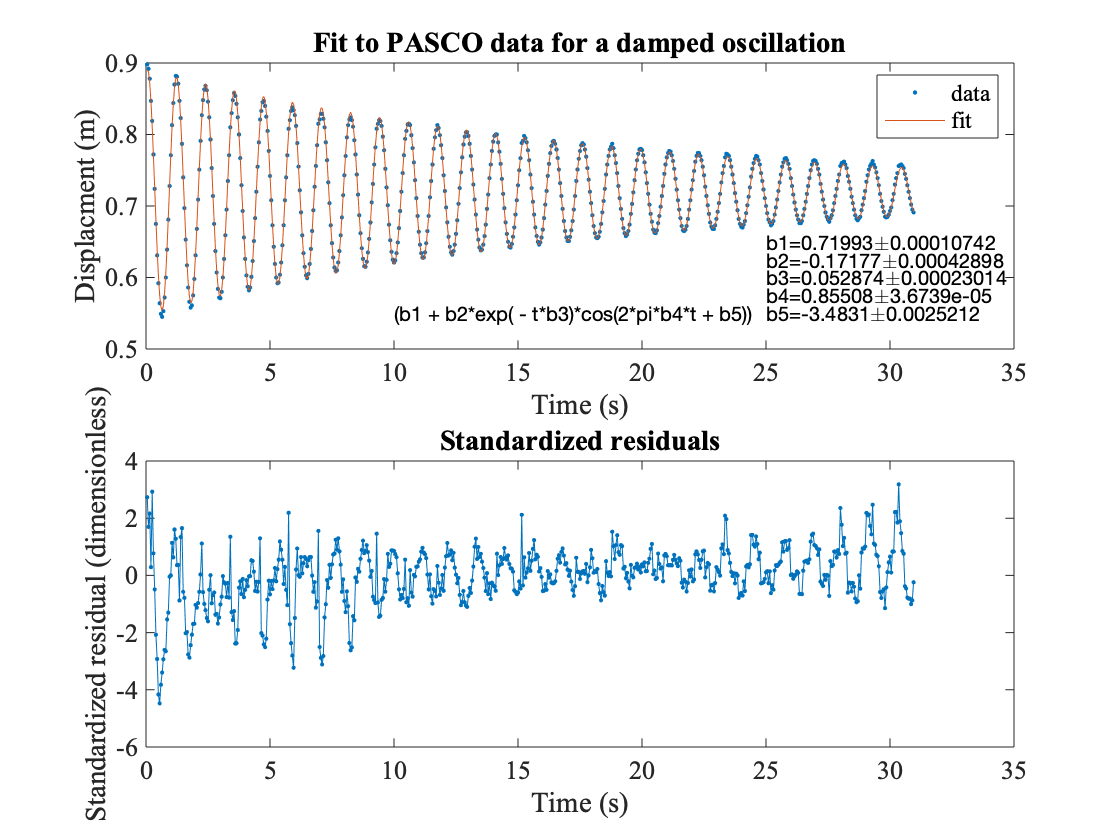

subplot(2,1,1)
plot(Times(range),Positionm(range),'.')
hold on
plot(Times(range),S.Fitted)
hold off
title('Fit to PASCO data for a damped oscillation')
xlabel('Time (s)');ylabel('Displacment (m)')
legend('data','fit')
text(10,.55,S.Formula.Expression)
y1=0.65;offset=0.025;
y2=y1-offset;y3=y2-offset;y4=y3-offset;y5=y4-offset;
text(25,y1,['b1=',num2str(b0(1)),'\pm',num2str(b0err(1))])
text(25,y2,['b2=',num2str(b0(2)),'\pm',num2str(b0err(2))])
text(25,y3,['b3=',num2str(b0(3)),'\pm',num2str(b0err(3))])
text(25,y4,['b4=',num2str(b0(4)),'\pm',num2str(b0err(4))])
text(25,y5,['b5=',num2str(b0(5)),'\pm',num2str(b0err(5))])
subplot(2,1,2)
plot(Times(range),S.Residuals.Standardized,'.-')
xlabel('Time (s)');ylabel('Standardized residual (dimensionless)')
title('Standardized residuals')

We see the fit has trouble at large absolute value of displacement. This could indicate a failure in the linear damping model. it might also result from a sonar displacement sensing nonlinearity.

function [VarName1,DateandTime,Times,Positionm,Velocityms,Accelerationms] = importfile(filename, startRow, endRow)
%IMPORTFILE Import numeric data from a text file as column vectors.
%   [VARNAME1,DATEANDTIME,TIMES,POSITIONM,VELOCITYMS,ACCELERATIONMS] =
%   IMPORTFILE(FILENAME) Reads data from text file FILENAME for the default
%   selection.
%
%   [VARNAME1,DATEANDTIME,TIMES,POSITIONM,VELOCITYMS,ACCELERATIONMS] =
%   IMPORTFILE(FILENAME, STARTROW, ENDROW) Reads data from rows STARTROW
%   through ENDROW of text file FILENAME.
%
% Example:
%   [VarName1,DateandTime,Times,Positionm,Velocityms,Accelerationms] = importfile('PASCOOscillationDat.txt',3, 622);
%
%    See also TEXTSCAN.

% Auto-generated by MATLAB on 2019/11/12 13:42:22

%% Initialize variables.
delimiter = '\t';
if nargin<=2
    startRow = 3;
    endRow = inf;
end

%% Format for each line of text:
%   column1: text (%s)
%	column2: datetimes (%{MM/dd/yyyy hh:mm:ss a}D)
%   column3: double (%f)
%	column4: double (%f)
%   column5: double (%f)
%	column6: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%s%{MM/dd/yyyy hh:mm:ss a}D%f%f%f%f%[^\n\r]';

%% Open the text file.
fileID = fopen(filename,'r');

%% Read columns of data according to the format.
% This call is based on the structure of the file used to generate this
% code. If an error occurs for a different file, try regenerating the code
% from the Import Tool.
dataArray = textscan(fileID, formatSpec, endRow(1)-startRow(1)+1, 'Delimiter', delimiter, 'TextType', 'string', 'EmptyValue', NaN, 'HeaderLines', startRow(1)-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
for block=2:length(startRow)
    frewind(fileID);
    dataArrayBlock = textscan(fileID, formatSpec, endRow(block)-startRow(block)+1, 'Delimiter', delimiter, 'TextType', 'string', 'EmptyValue', NaN, 'HeaderLines', startRow(block)-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
    for col=1:length(dataArray)
        dataArray{col} = [dataArray{col};dataArrayBlock{col}];
    end
end

%% Close the text file.
fclose(fileID);

%% Post processing for unimportable data.
% No unimportable data rules were applied during the import, so no post
% processing code is included. To generate code which works for
% unimportable data, select unimportable cells in a file and regenerate the
% script.

%% Allocate imported array to column variable names
VarName1 = dataArray{:, 1};
DateandTime = dataArray{:, 2};
Times = dataArray{:, 3};
Positionm = dataArray{:, 4};
Velocityms = dataArray{:, 5};
Accelerationms = dataArray{:, 6};

% For code requiring serial dates (datenum) instead of datetime, uncomment
% the following line(s) below to return the imported dates as datenum(s).

% DateandTime=datenum(DateandTime);

end

